# EKG Classification using Wavelet Scattering and LSTMs

This example shows how to classify human electrocardiogram (ECG) signals using wavelet time scattering and LSTM. We will be training a Long Short-Term Memory network to recognize the following heart rhythms:

- *Normal Sinus Rhythm (NSR)*

- * Arrythmia (ARR) *

- *Congestive Heart Failure (CHF)*

## Load and Preprocess Data

load("ECGData.mat"); 

## Automatic Feature Extraction using Wavelet Scattering

Wavelet scattering is a technique that can be used to automatically extract low-variance, compact features in such a way that minimizes the differences within a class while preserving discriminability across classes. 

Instead of feeding the raw representations to LSTMs, we can provide these features so that the network can quickly learn the patterns and subsequently classify the signals. 

sampleSig = ECGData.Data(1,:);
sf = waveletScattering('SignalLength',numel(sampleSig),'SamplingFrequency',Fs)

sf =   waveletScattering with properties:

          SignalLength: 65536
       InvarianceScale: 256
        QualityFactors: [8 1]
              Boundary: 'periodic'
     SamplingFrequency: 128
             Precision: 'double'
    OversamplingFactor: 0
          OptimizePath: 0


feat = featureMatrix(sf,sampleSig);

The variable `feat` contains the autoamtically extracted features from the signal.  In this example we are using a 2 layer network to extract all the features.

whos sampleSig

  Name           Size                Bytes  Class     Attributes

  sampleSig      1x65536            524288  double              



whos feat

  Name        Size            Bytes  Class     Attributes

  feat      492x8             31488  double              



***95% ****reduction in size of features (compared to length of original signal)*

### Visualize the Features Extracted 

We can examine the features coming from each layer independently

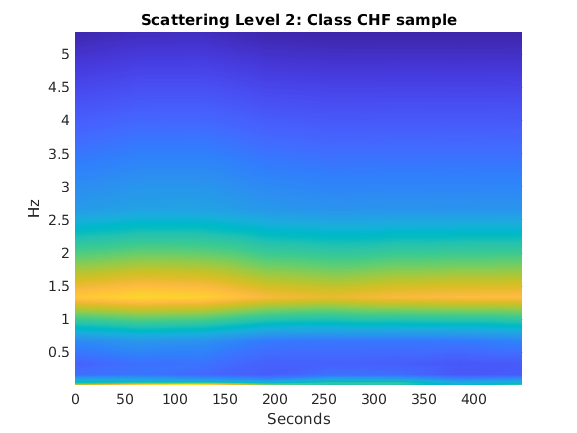

lev = 2;
signalClass = "CHF";
[S,~] = scatteringTransform(sf,ECGData.Data(find(ECGData.Labels==signalClass,1),:));

scattergram(sf,S,'FilterBank',lev);
title(sprintf('Scattering Level %d: Class %s sample', lev, signalClass));

Note: What we have shown above is just a way of visualizing what features have been extracted. A matrix of 499x8 features is extracted for each signal. 

### **Extract Features for all Signals in Training and Test **

Let's load a prepartitioned dataset that's been partitioned randomly into a training datset and a testing dataset.

load("PartitionedData.mat")

Using our existing wavelet scattering transform, compute the scatter features for the training and testing datasets.

scat_features_train = cell(113,1);
scat_features_test = cell(49,1);

parfor itr = 1:113   %113 Training Records
    tmp = featureMatrix(sf,trainData(itr,:));
    scat_features_train{itr,1} =tmp;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).



parfor ttr = 1:49    % 49 Test Records
    % Store the featureMatrix of testData 
    tmp = featureMatrix(sf,testData(ttr,:));
    scat_features_test{ttr,1} =tmp;
end

## Train a LSTM on Scattering Features

### Create the network layers 

Let's now set up a very simple LSTM network to train. Retrain with different values of hidden units in the lstmLayer.  

[inputSize,~] = size(scat_features_train{1});
numClasses = 3; 
numHiddenUnits = 220; 

% Store the LSTM Network in the variable "layers"
% [ADD CODE HERE]
% Store the LSTM Network in the variable "layers"
layers = [
    sequenceInputLayer(492,"Name","sequence")
    lstmLayer(200,"Name","lstm")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];


 Alternatively use the Deep Network Designer App to create these layers 

deepNetworkDesigner

### **Train the Network**

Retrain the network. Use the following training options and save them to variable "opts"

- `InitialLearnRate 0.01`

- `MaxEpochs        125 `

- `MiniBatchSize    1000`

- `SequenceLength   'shortest'`

- `Shuffle          'never'`

- `Plots            'training-progress' `

`Hint : ``doc trainingOptions `

% [ADD CODE HERE]
opts = trainingOptions('adam', ...
    'InitialLearnRate',0.01,...
    'MaxEpochs',125, ...
    'MiniBatchSize',1000, ...
    'SequenceLength','shortest', ...
    'Shuffle','never',...
    'Plots','training-progress');

Now train the network and save it to variable "ECGScatNet"

`Hint : ``doc trainNetwork `

YTrain = categorical(trainLabels); % Use this as labels input argument for trainNetwork 
ECGScatNet = trainNetwork(scat_features_train,YTrain,layers,opts);

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:23 |       53.98% |       1.0957 |          0.0100 |
|      50 |          50 |       00:00:25 |       99.12% |       0.0685 |          0.0100 |
|     100 |         100 |       00:00:26 |      100.00% |       0.0003 |          0.0100 |
|     125 |         125 |       00:00:26 |      100.00% |       0.0003 |          0.0100 |
|========================================================================================|


### **Evaluate LSTM model **

Now we can test our fully trained model:

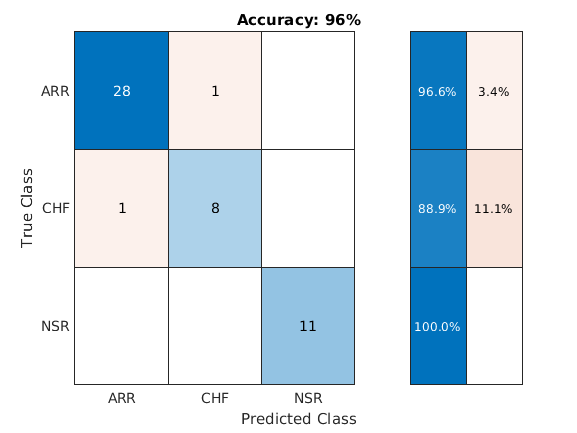

YTest = categorical(testLabels);

% Use the classify function on the ECGScatNet on test data 
% [ADD CODE HERE]
YPred = classify(ECGScatNet,scat_features_test);
accuracy = round((sum(YPred == YTest)./numel(YTest))*100);

confusionchart(YTest, YPred, "RowSummary", "row-normalized");
title("Accuracy: " + accuracy + "%")

### Improving the Classification Accuracy

If you are not satisfied with the results, there is an optional parameter of the scattering filterbank that you can fine tune to achieve desired results. The default value of the invariance scale is is half the signal length (in samples)

You can always sweep the Invariance Scale and use bayesian optimization to figure out the right hyperparameters of LSTMs network to figure out the right combination of parameters 

## Summary

This example used wavelet time scattering and an LSTM to classify ECG waveforms into one of three diagnostic classes. Wavelet scattering proved to be a powerful feature extractor, which required only a minimal set of user-specified parameters to yield a set of robust features for classification. 

*Copyright 2020 The MathWorks, Inc.*